#  Concrete Strength

Concrete mixtures have several variations. This data set is a case study for data visualization and exploration to predict the concrete compressive strength (MPa).

This case study is to determine the factors (inputs) that have correlation to the concrete compressive strength (output). Use visualization and exploration to gain an understanding of the data and make decisions about how it can be applied to predict strength. Use the data to determine data diversity, relationships, missing data, bad data, and factors that are important for regression. This case study uses data from [**concrete samples**](https://apmonitor.com/pds/uploads/Main/cement_strength.txt) that is also posted to [**Revisting a Concrete Strength Regression on Kaggle**](https://www.kaggle.com/maajdl/yeh-concret-data).

## Description

Concrete strength is affected by factors such as water to cement ratio, raw material quality, the ratio of coarse or fine aggregate, concrete age, concrete compaction, temperature, relative humidity, and other factors during the curing of the concrete. The data includes the following information for 1030 concrete samples.

**Input variable:**

- Cement: kg/m3 mixture

- Blast Furnace Slag: kg/m3 mixture

- Fly Ash: kg/m3 mixture

- Water: kg/m3 mixture

- Superplasticizer: kg/m3 mixture

- Coarse Aggregate: kg/m3 mixture

- Fine Aggregate: kg/m3 mixture

- Age: Day (1 to 365)

**Output variable:**

- Concrete compressive strength: MPa

## Activity 1: Data Visualization and Exploration

Use the first activity to complete the case study on data visualization and exploration.

% Import the data and read the first 10 rows
url = 'http://apmonitor.com/pds/uploads/Main/cement_strength.txt';
df = readtable(url);
df(1:20,:)

ans = 20×9 table
    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____

      540         0      0        162           2.5                 1040               676         28    79.99
      540         0      0        162           2.5                 1055               676         28    61.89
    332.5     142.5      0        228             0                  932               594        270    40.27
    332.5     142.5      0        228             0                  932               594        365    41.05
    198.6 

## 1-D plots

1-dimensional plots are useful for plotting distributions of a single feature. It enables quick observations to see if the data is clean or if it needs some preprocessing. 

Download the file for the violin.m function at [https://www.mathworks.com/matlabcentral/fileexchange/45134-violin-plot](https://www.mathworks.com/matlabcentral/fileexchange/45134-violin-plot) and as to MathWorks\MATLAB Add-Ons\Functions or download through MATLAB by navigating to Home--> Add-Ons--> Get Add-Ons--> Search for violin.m

There are many ways to visualize the distribution, several of which are shown below:

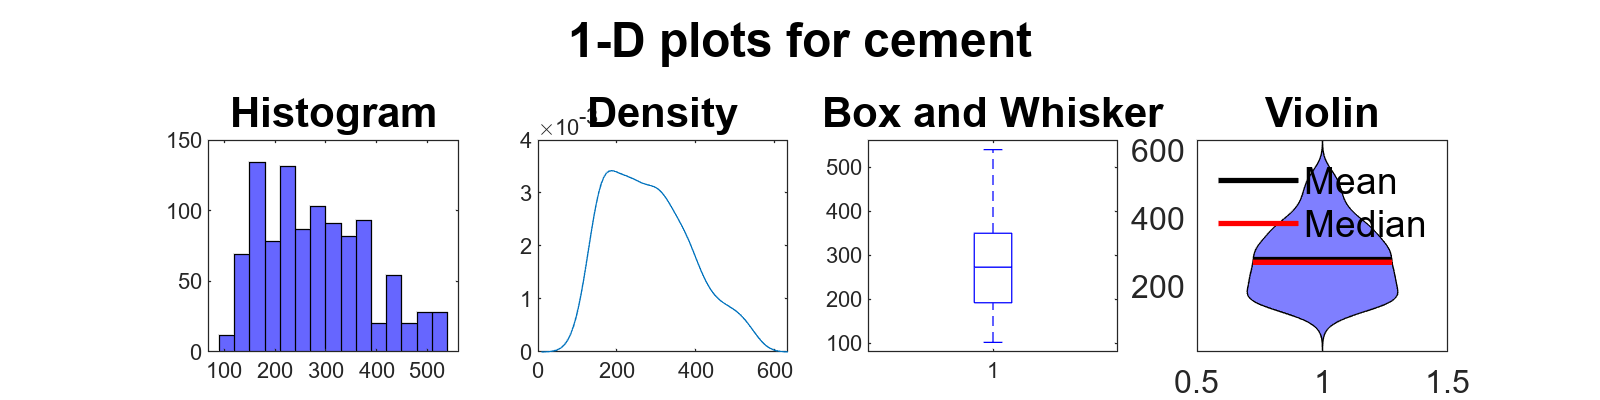

col = 'cement';

figure('Position', [0, 0, 800, 200]);
sgtitle(sprintf('1-D plots for %s', col), 'FontSize', 18, 'FontWeight', 'bold');

clear title
subplot(1, 4, 1);
histogram(df.(col), 'FaceColor', 'b');
title('Histogram', 'FontSize', 16);

subplot(1, 4, 2);
ksdensity(df.(col));
title('Density', 'FontSize', 16);

subplot(1, 4, 3);
boxplot(df.(col), 'Colors', 'b');
title('Box and Whisker', 'FontSize', 16);

subplot(1, 4, 4);
violin(df.(col), 'facecolor','b', 'linecolor', 'b', 'medc', 'r');
title('Violin', 'FontSize', 16);

### **Activity:** 

Create a series of 1-dimensional plots to visualize the distribution of concrete strength `csMPa` in MPa.

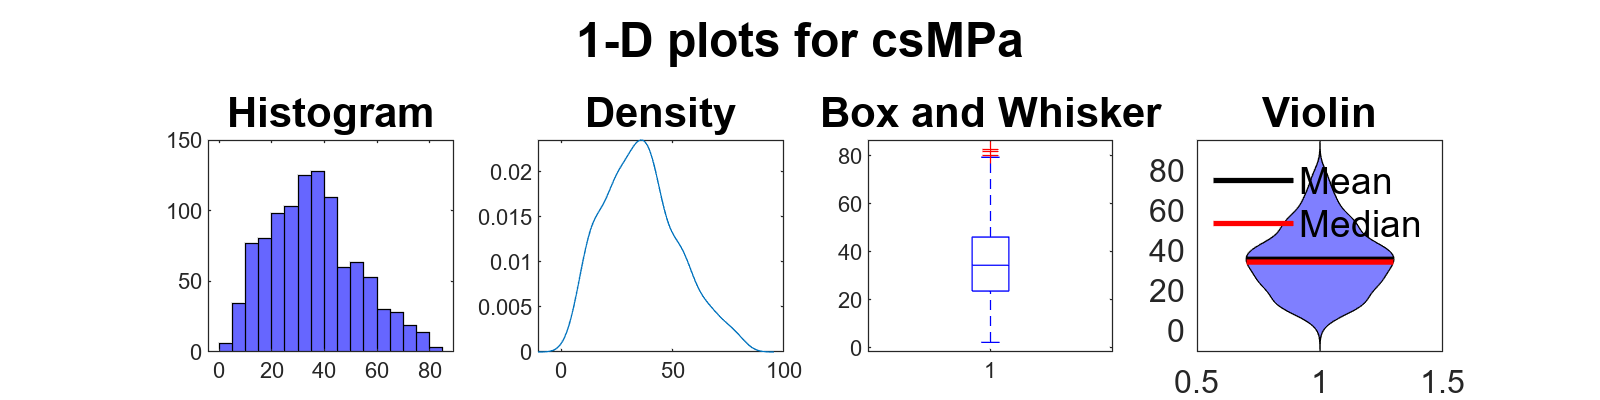

col = 'csMPa';

figure('Position', [0, 0, 800, 200]);
sgtitle(sprintf('1-D plots for %s', col), 'FontSize', 18, 'FontWeight', 'bold');

subplot(1, 4, 1);
histogram(df.(col), 'FaceColor', 'b');
title('Histogram', 'FontSize', 16);

subplot(1, 4, 2);
ksdensity(df.(col));
title('Density', 'FontSize', 16);

subplot(1, 4, 3);
boxplot(df.(col), 'Colors', 'b');
title('Box and Whisker', 'FontSize', 16);

subplot(1, 4, 4);
violin(df.(col), 'facecolor','b', 'linecolor', 'b', 'medc', 'r');
title('Violin', 'FontSize', 16);

## 2-D plots

2-dimensional plots are particularly useful to show correlations between two features. This could be useful to give you an idea of important features to predict an output with a machine learning model.

- **Line plots:** shows time series; since there is no time element in this dataset, this will not be shown here. To create a line plot, use plt.plot(data)

- **Scatter plots:** shows correlations between two features. Consider log scales for data that spans several orders of magnitude

- **Pairplots and jointplots:** seaborn plots that show both the distribution and correlations

- **Heatmap:** compute correlations between features using Pandas df.corr(). Highly correlated features are often redundant and slow down the analysis without improving results

- **Grouped 1-D plots:** distributions of a single column of data that are grouped based on an independent feature

**Scatter Plot:**

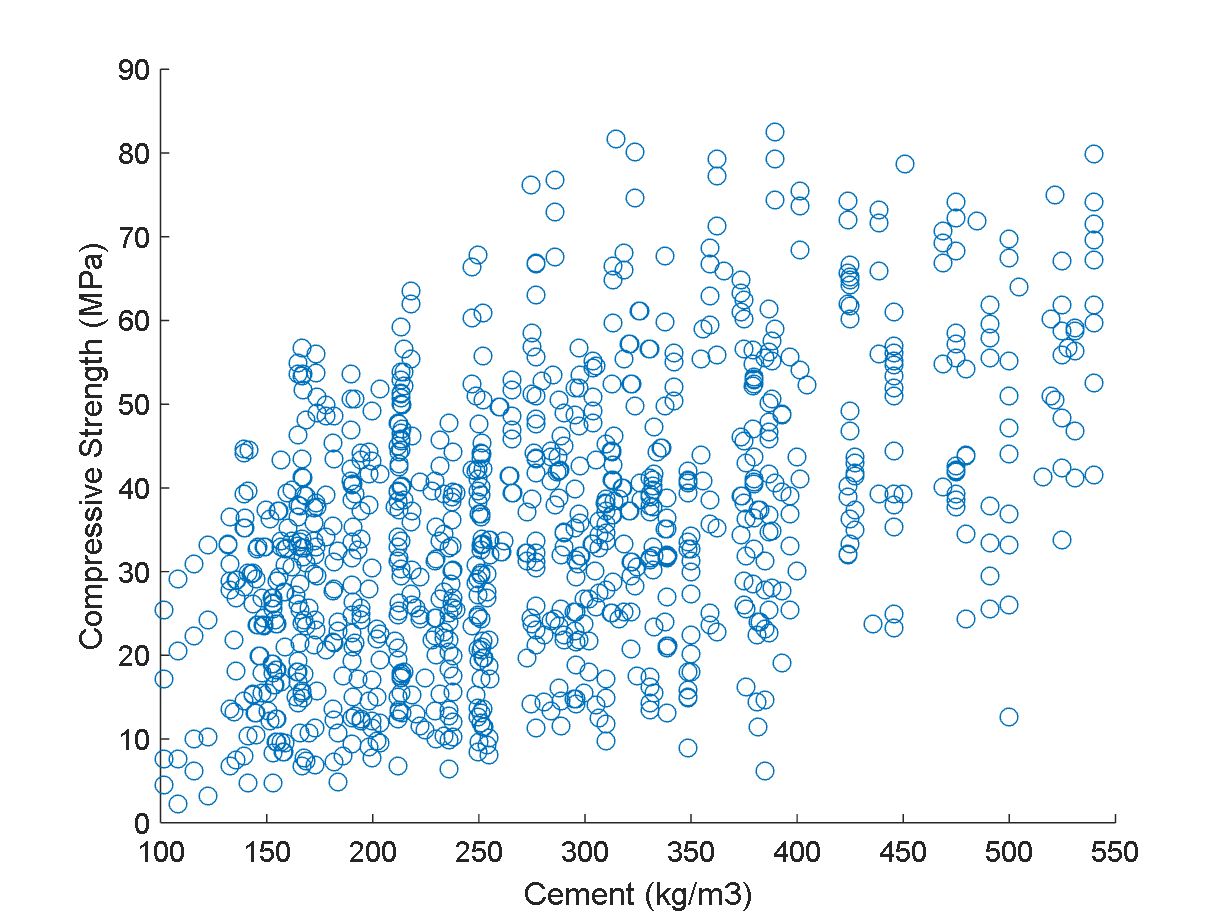

% Scatter plot
x = df.cement;
y = df.csMPa;

figure;
scatter(x,y);
xlabel('Cement (kg/m3)');
ylabel('Compressive Strength (MPa)');

**Pair Plot:**

Download the file for the pairplot function at [https://www.mathworks.com/matlabcentral/fileexchange/60866-pairplot-meas-label-group-colors-mode](https://www.mathworks.com/matlabcentral/fileexchange/60866-pairplot-meas-label-group-colors-mode) or download through MATLAB by navigating to Home--> Add-Ons--> Get Add-Ons--> Search for pairplot

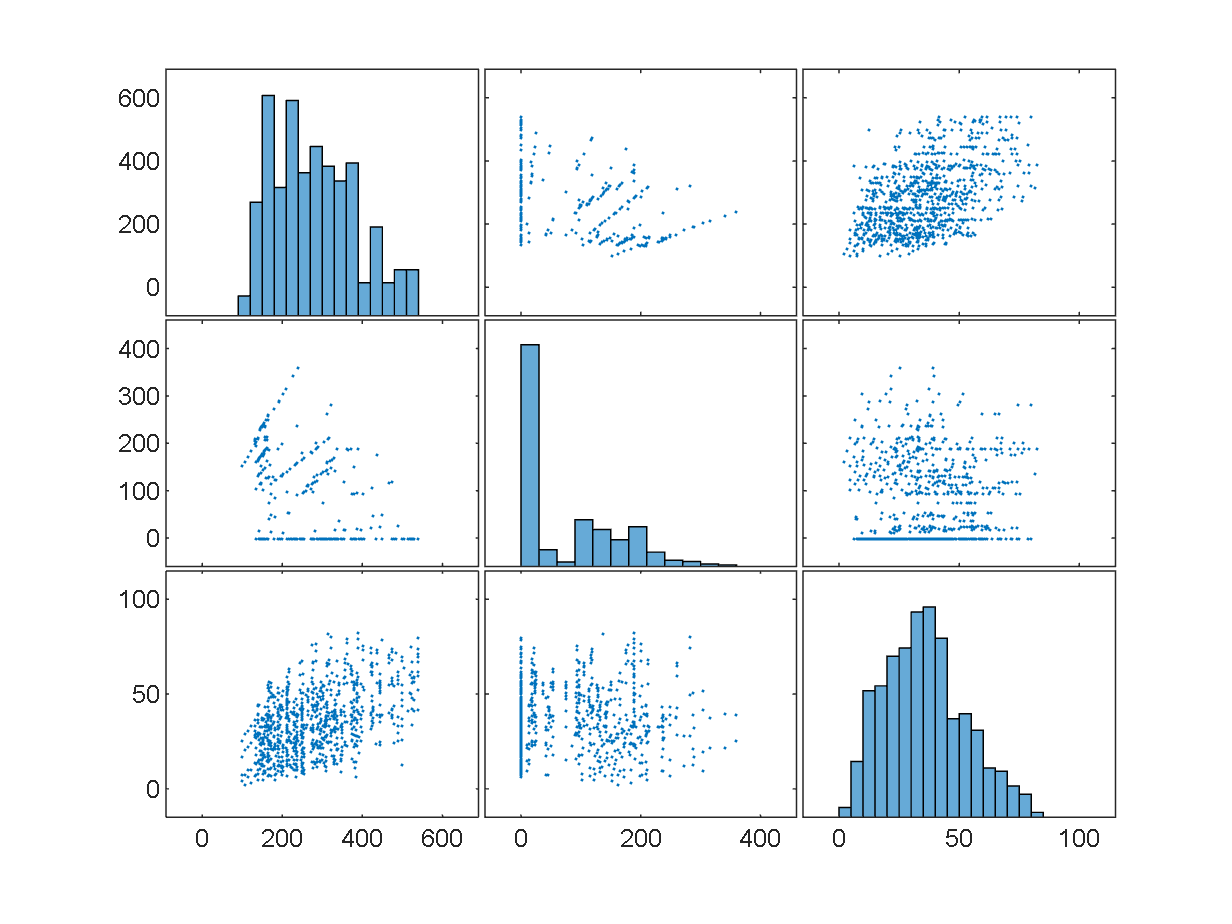

% Extract variables of interest
vars = {'cement', 'slag', 'csMPa'};
X = df{:, vars};

% Create pair plot
plotmatrix(X)

**Joint Plot**

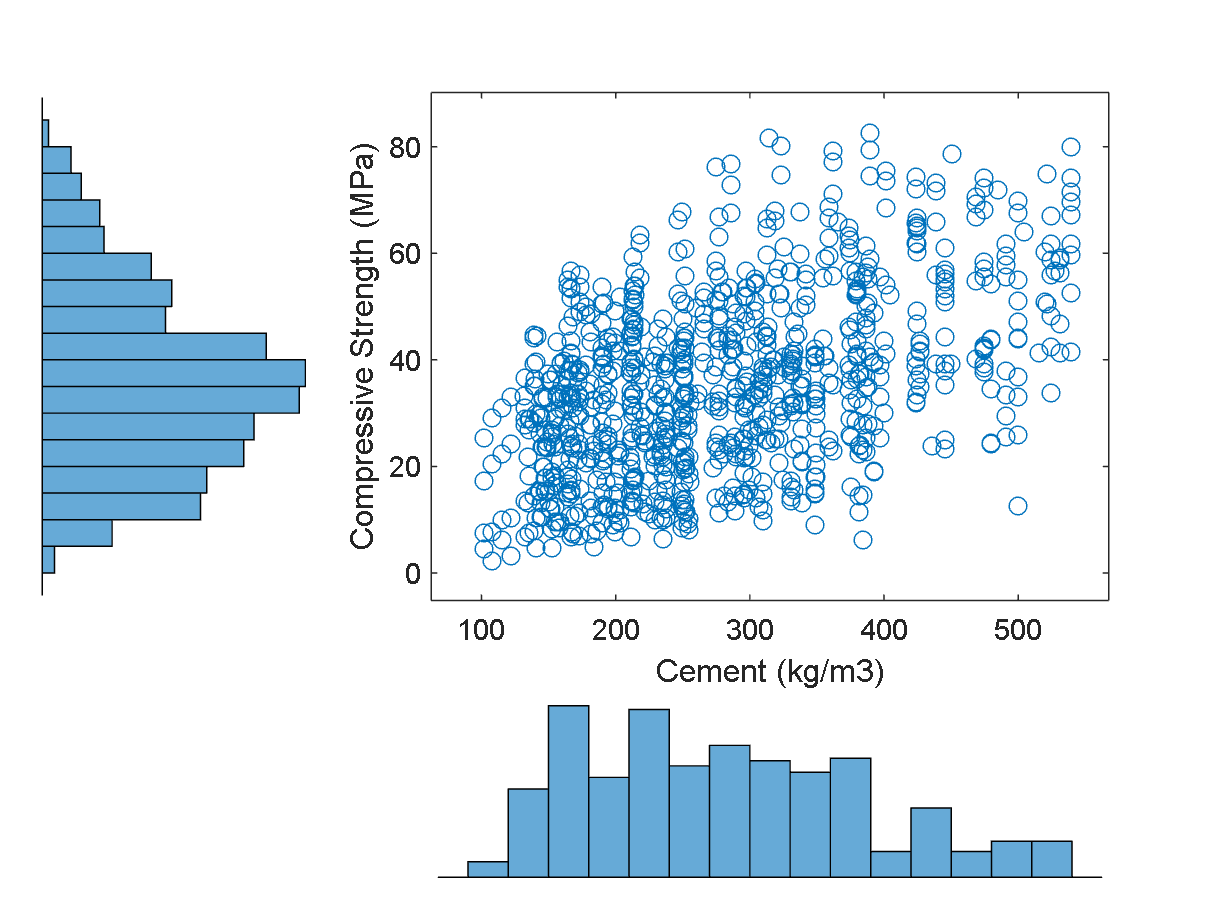

%Jointplot
x = df.cement;
y = df.csMPa;

figure;
scatterhist(x,y);
xlabel('Cement (kg/m3)');
ylabel('Compressive Strength (MPa)');

**Heatmap**

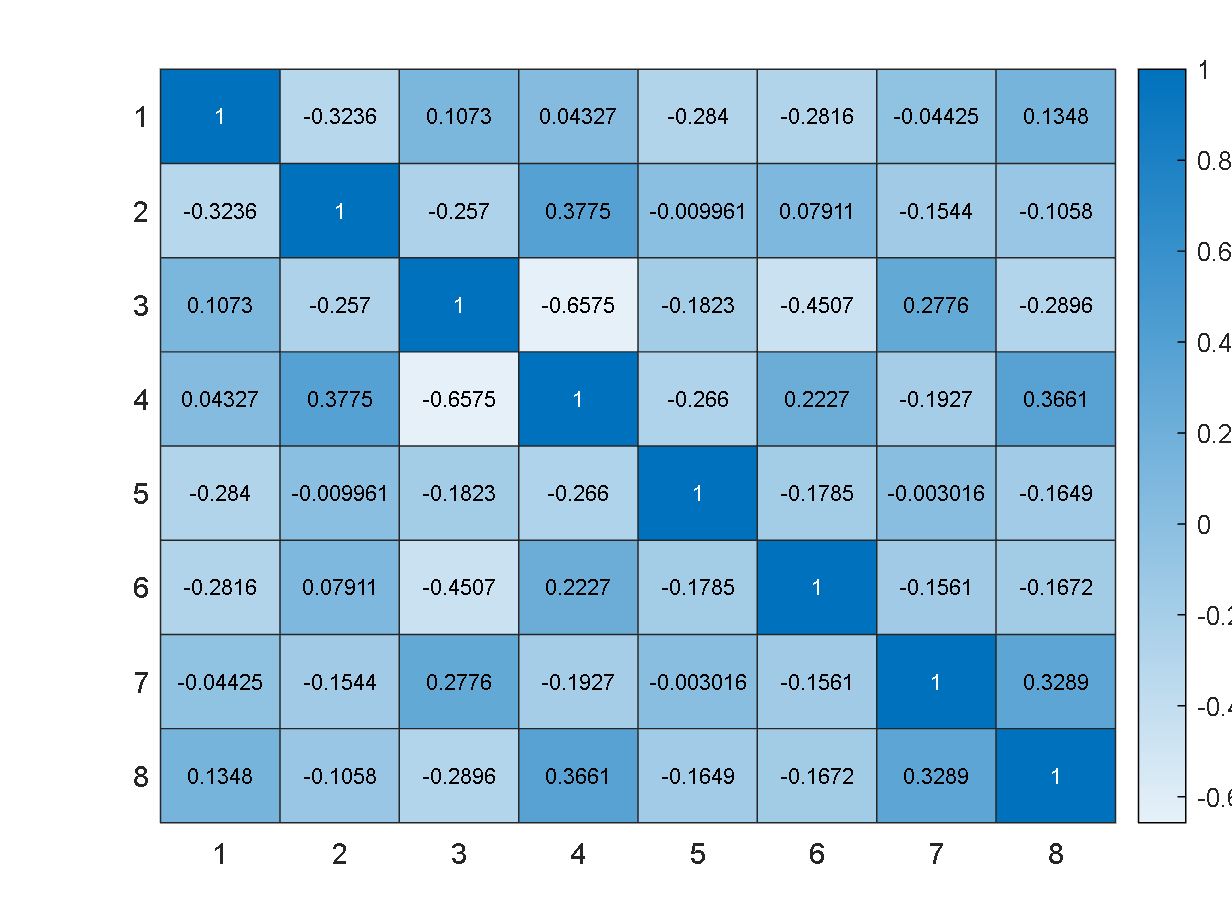

% Compute correlation matrix
corr_matrix = corr(df{:, 2:end});
%create a heatmap of the correlation matrix
%1.0 means exactly correlated, -1.0 means exactly inversely correlated, and 0.0 means no correlation
heatmap(corr_matrix)

Grouped 1D plot

% Grouped 1-D plot
% Group 'cement' based on csMPa > 35.0 or not

%df.Strength = df.csMPa %cellstr(char('Lo'*ones(size(df.cement))));
%df.Strength(df.csMPa > 35) = {'Hi'};
%df.Strength(df.csMPa < 35) = {'Lo'};
%for i = length(df.csMPa)
df = addvars(df,zeros(length(df.csMPa),1),'NewVariableNames', 'Strength'); % This adds a new column of zeros labled Strenth

high_strength_array = [];
high_strength_csMPa = [];
low_strength_array = [];
low_strength_csMPa = [];

for i = 1:length(df.csMPa)
    if df.csMPa(i) > 35
        df.Strength(i) = 1; % 1 = high strength
        high_strength_csMPa = [high_strength_csMPa df.csMPa(i)];
    else 
        df.Strength(i) = 0; % 0 = low strength
        low_strength_csMPa = [low_strength_csMPa df.csMPa(i)];
    end
end

df

df = 1030×10 table
    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa    Strength
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____    ________

      540         0      0        162           2.5                 1040               676         28    79.99       1    
      540         0      0        162           2.5                 1055               676         28    61.89       1    
    332.5     142.5      0        228             0                  932               594        270    40.27       1    
    332.5     142.5      

% Plotting Violin Graph
low_strength_csMPa(length(high_strength_csMPa)+1:end) = []; % snipping end of data off to ensure matrix lengths are the same size so violin plot function works
strength_arrays_to_graph = [high_strength_csMPa', low_strength_csMPa'];
violin(strength_arrays_to_graph);

% Add labels to each violin plot
text(1, max(high_strength_csMPa), 'High Strength', 'HorizontalAlignment', 'center', 'FontSize', 14);
text(2, max(low_strength_csMPa), 'Low Strength', 'HorizontalAlignment', 'center', 'FontSize', 14);

% Add axis labels and title
set(gca, 'XTickLabel', []);
ylabel('MPa');
title('Grouped 1-D Plot of Cement by Strength');

## Activity

Generate 2 types of 2-dimensional plots using 2 features of your choice (csMPa would be a useful feature to include, since that is the outpout feature you want to predict with regression

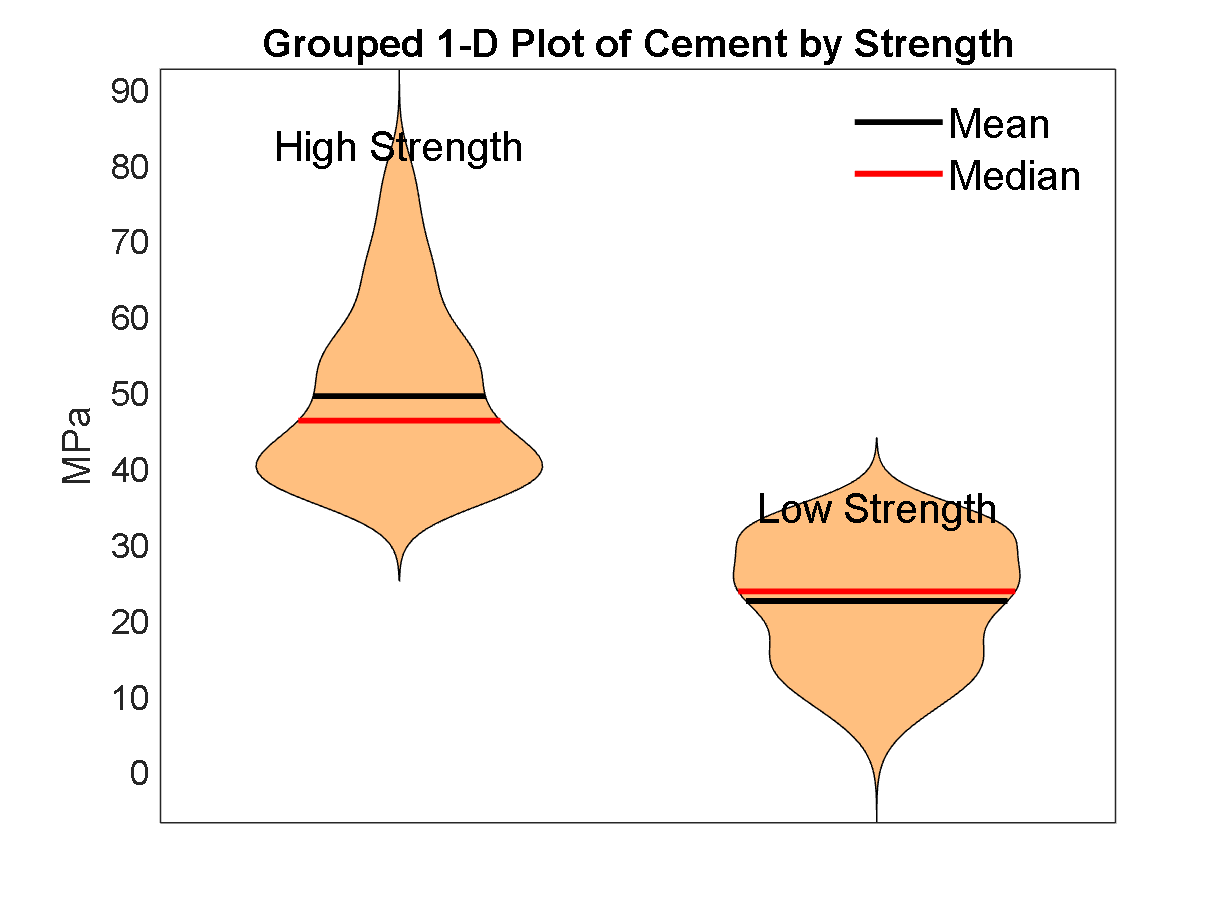

% Scatter plot
x = df.slag;

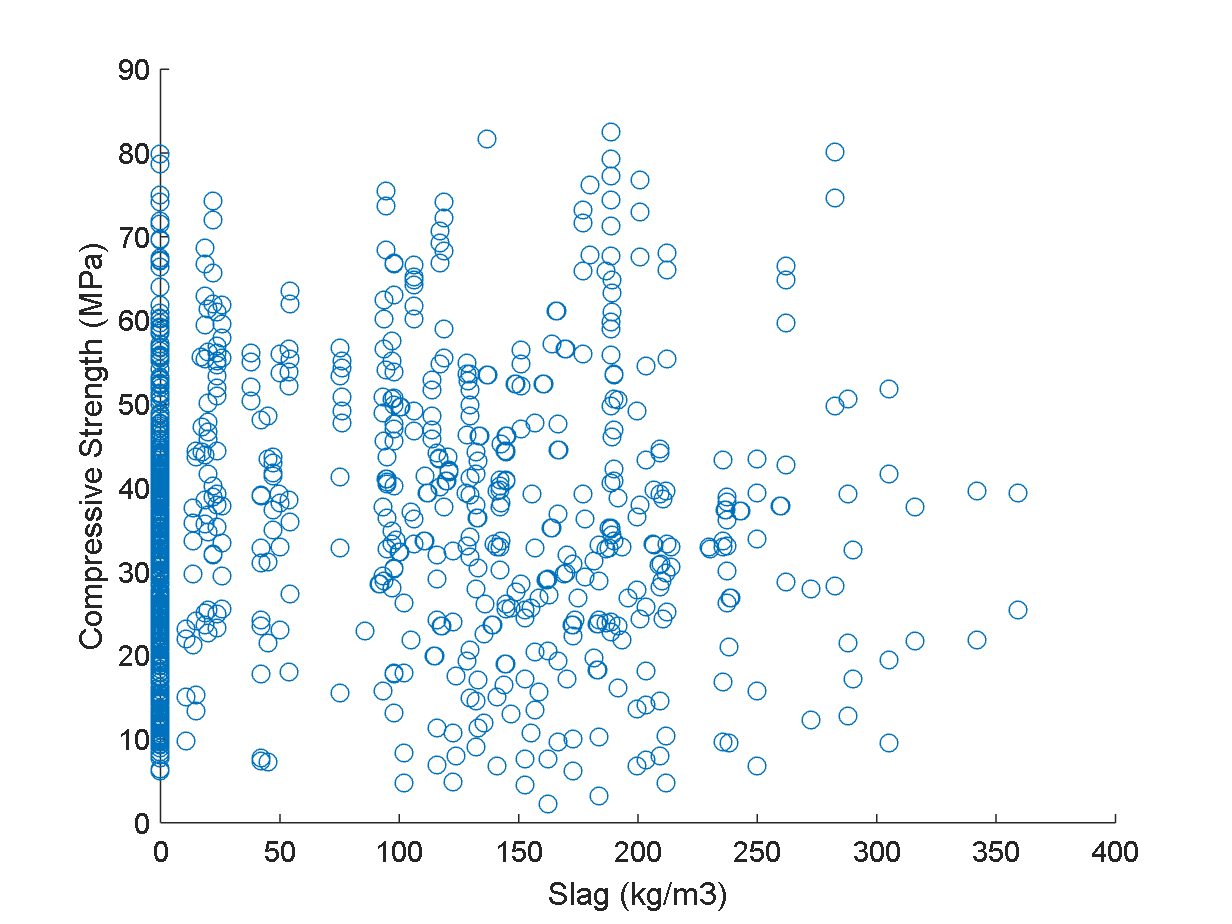

y = df.csMPa;

figure;
scatter(x,y);
xlabel('Slag (kg/m3)');
ylabel('Compressive Strength (MPa)');
%Volin Plot
data_matrix_to_graph = [df.water, df.csMPa];

violin(data_matrix_to_graph); % What does GroupOrder do? How do we separate the data into high's and low's to be plotted


% Add labels to each violin plot
text(1, max(df.water), 'Water', 'HorizontalAlignment', 'center', 'FontSize', 14);
text(2, max(df.csMPa), 'Cement Strength', 'HorizontalAlignment', 'center', 'FontSize', 14);

% Add a title and axis labels
set(gca, 'XTickLabel', []);
title('Violin plots of Water and Strenth');
ylabel('MPa, Kg/m3');

## Multi-dimensional Plots

Multidimensional plots visualize more complex relationships. However, natural intuition begins to break down as more dimensions are introduced, so be careful when introducing too many features in a single plot.

- 3-D scatter plots show correlations between 3 features. However, visualizing the 3-D plot on a 2-D screen can present challenges. See the "Other plotting options" section for alternatives

- Grouping methods can continue to show more features on a 2-D plot by adjusting the color, size, or shape of the marker; be sure to include a legend

- Principal Component Analysis (PCA) reduces dozens of features by tranforming to a lower dimensional space. The principal component directions and magnitudes are computed using the _________

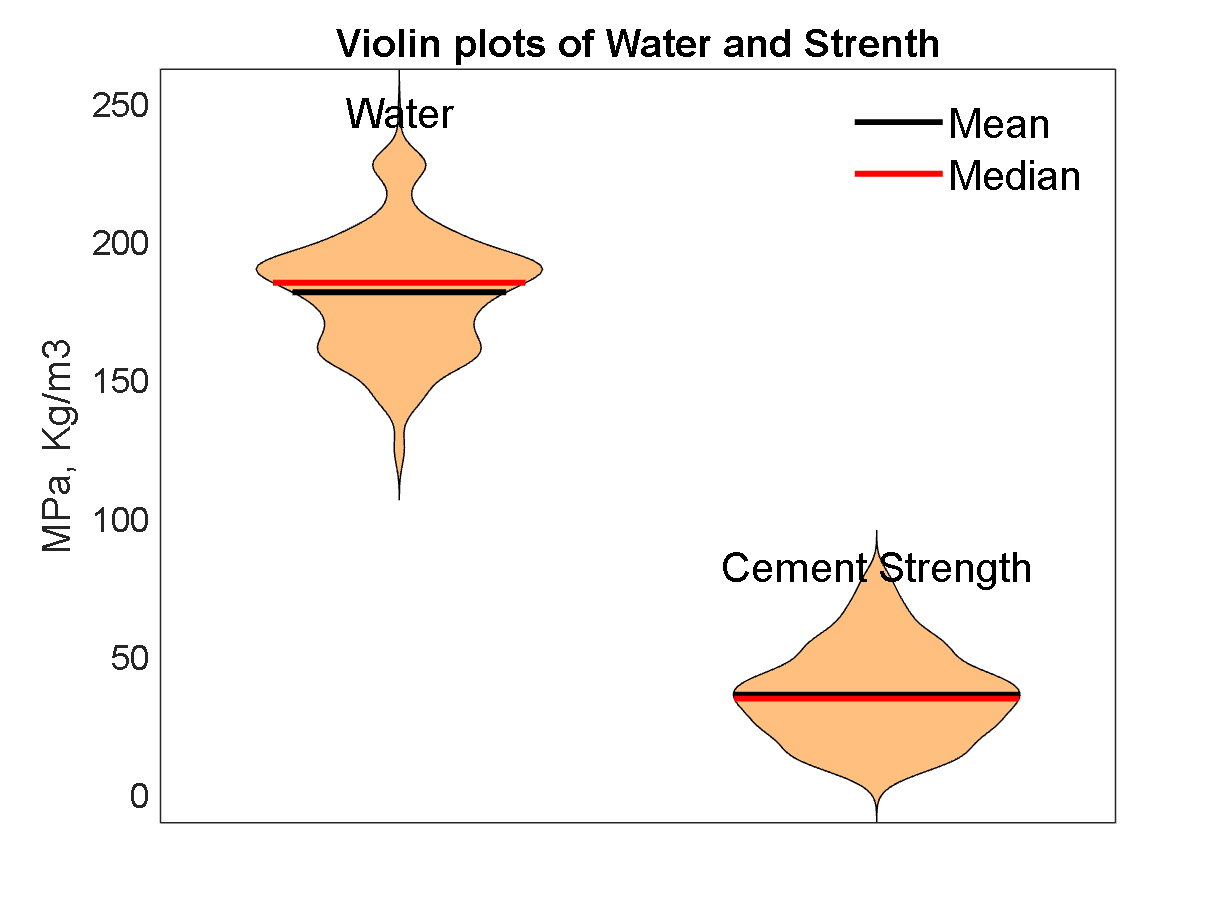

% 3-D scatter plot
x = df.cement;
y = df.slag;
z = df.csMPa;


figure;
scatter3(x,y,z);
xlabel('Cement (kg/m3)');
ylabel('Slag (kg/m3)');
zlabel('Compressive Strength (MPa)');

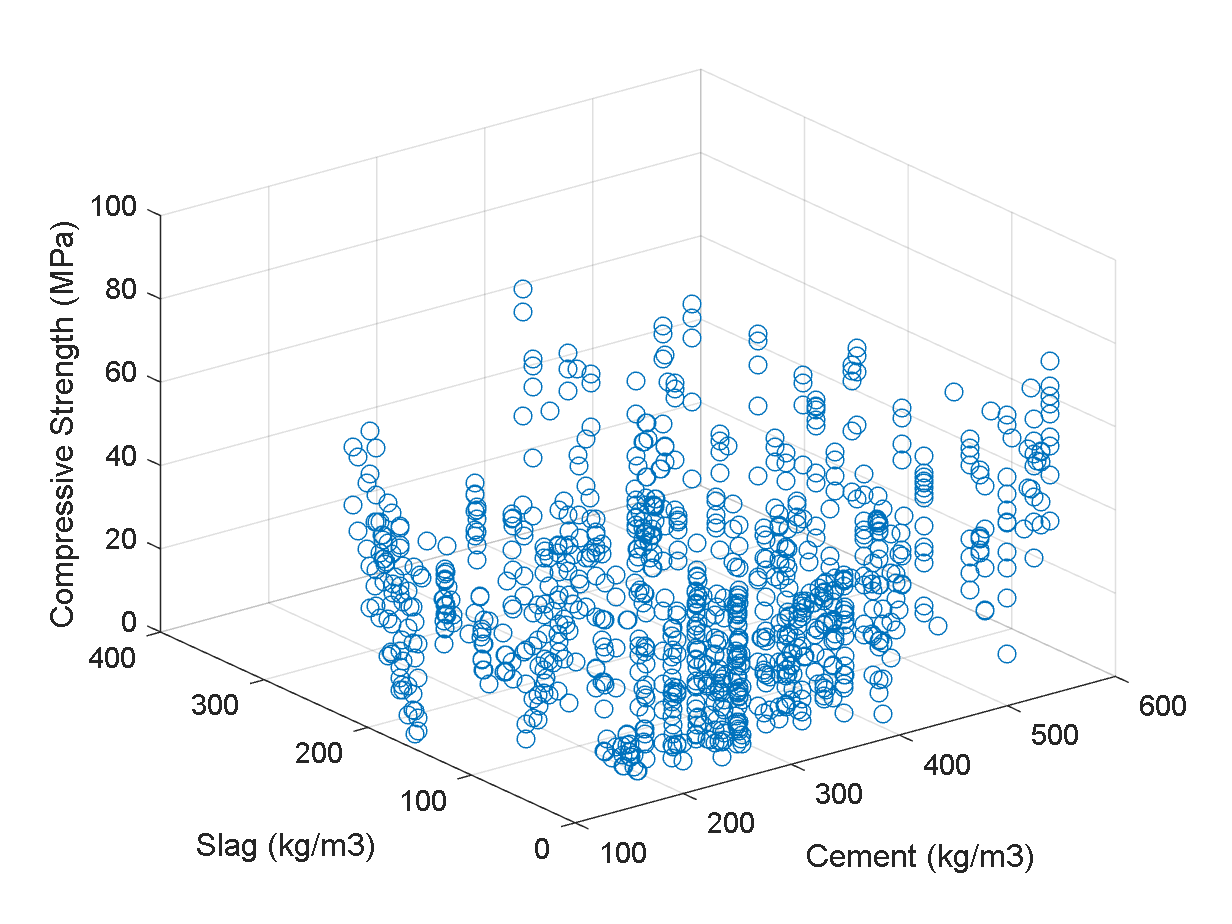

% Grouping Plot By Point Size
x = df.cement;
y = df.slag;
s = df.csMPa;

scatter(x, y, s, 'filled');
title('Grouping Plot By Point Size');
xlabel('Cement (Kg/m3)');

ylabel('Slag (kg/m3)');
smallest_point = num2str(min(df.csMPa));
largest_point = num2str(max(df.csMPa));
smallest_point, largest_point % legend for grouping plot

% Grouping Plot By Color
scatter(df,'cement','slag','filled','ColorVariable','csMPa');
title('Grouping Plot By Color');
c = colorbar;
c.Label.String = 'MPa';

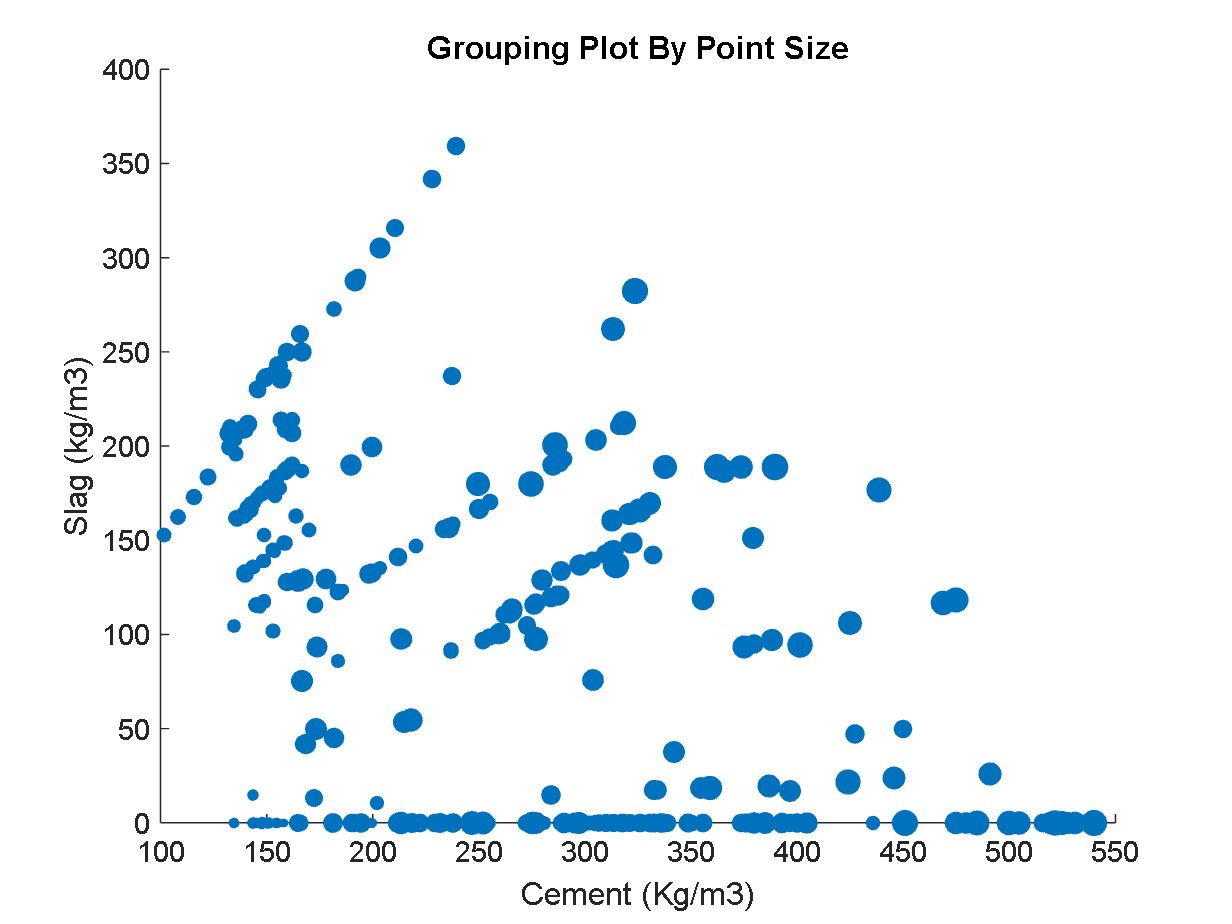

% Grouping Plot by Color and Size

x = df.cement;
y = df.slag;
s = df.csMPa; % Size

smallest_point = '2.33'

largest_point = '82.6'

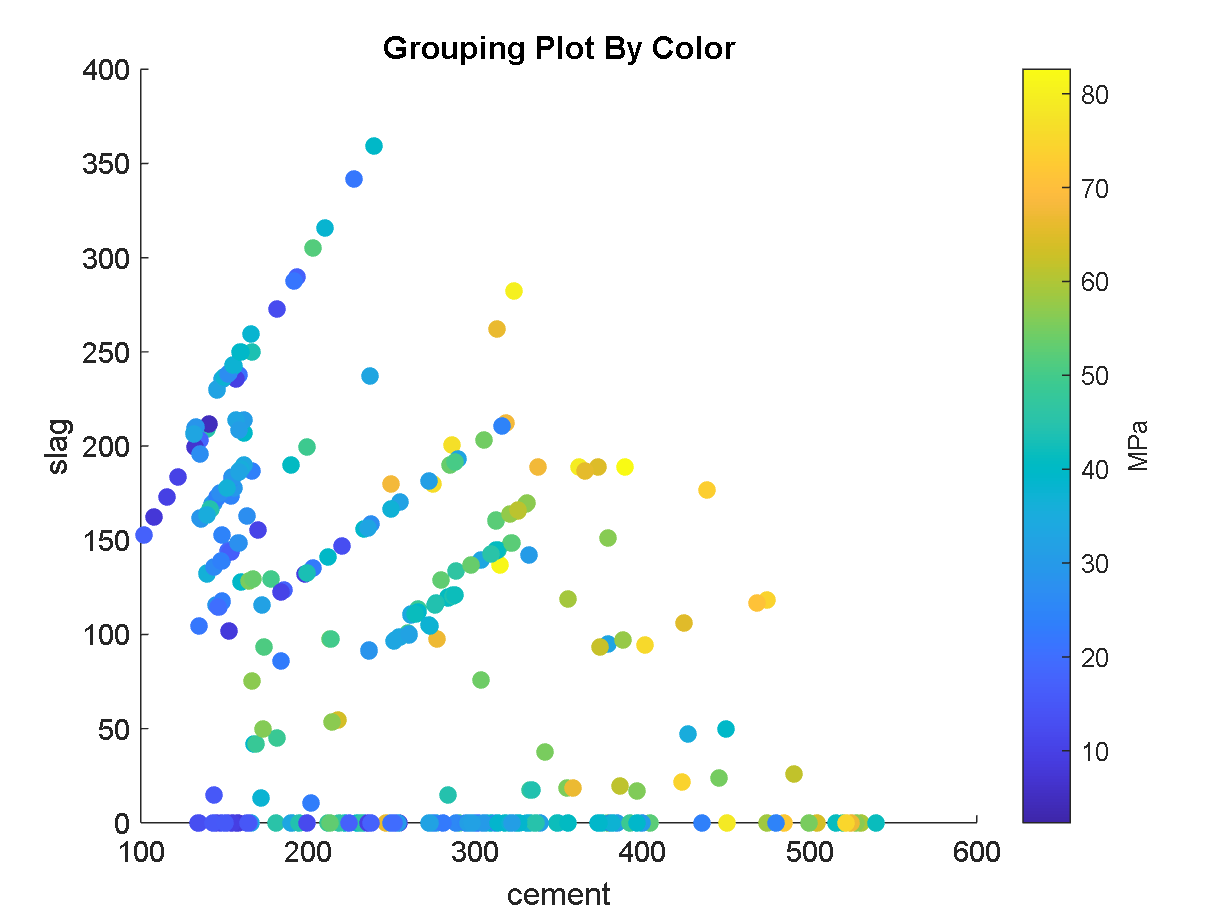

c = df.csMPa; % Color

scatter(x, y, s, c, 'filled'); % No idea how to do this
color = colorbar;
color.Label.String = 'MPa';
title('Grouping Plot By Color and Point Size');

xlabel('Cement (Kg/m3)');
ylabel('Slag (kg/m3)');

% PCA
df_matrix = table2array(df);
[~, score] = pca(df_matrix);

% Create scatter plot of principal component scores
scatter(score(:,1), score(:,2));
title('PCA Plot');


**Activity:** Create a multidimensional plot of at least 3 features and plot them.

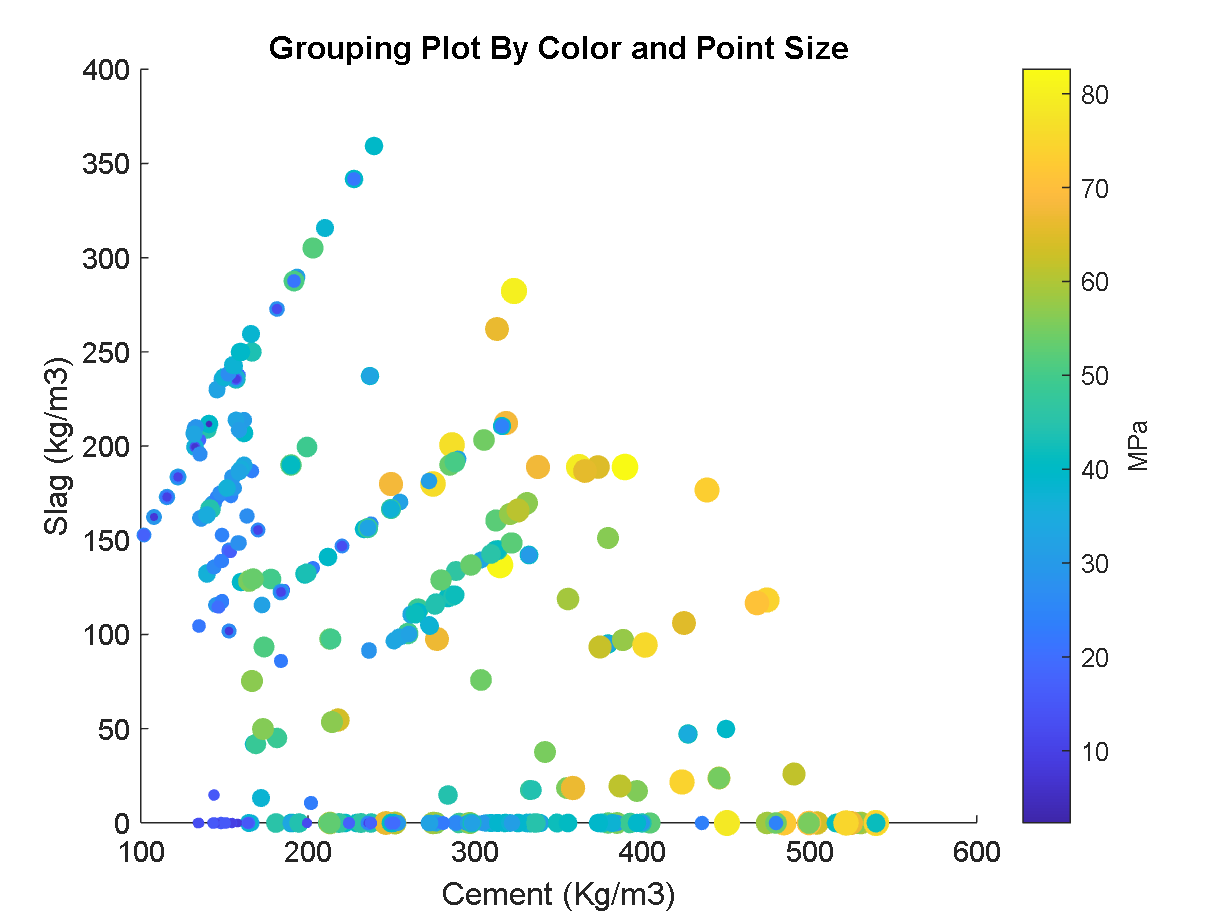

% This is a 5D graph
x = df.coarseaggregate;
y = df.water;

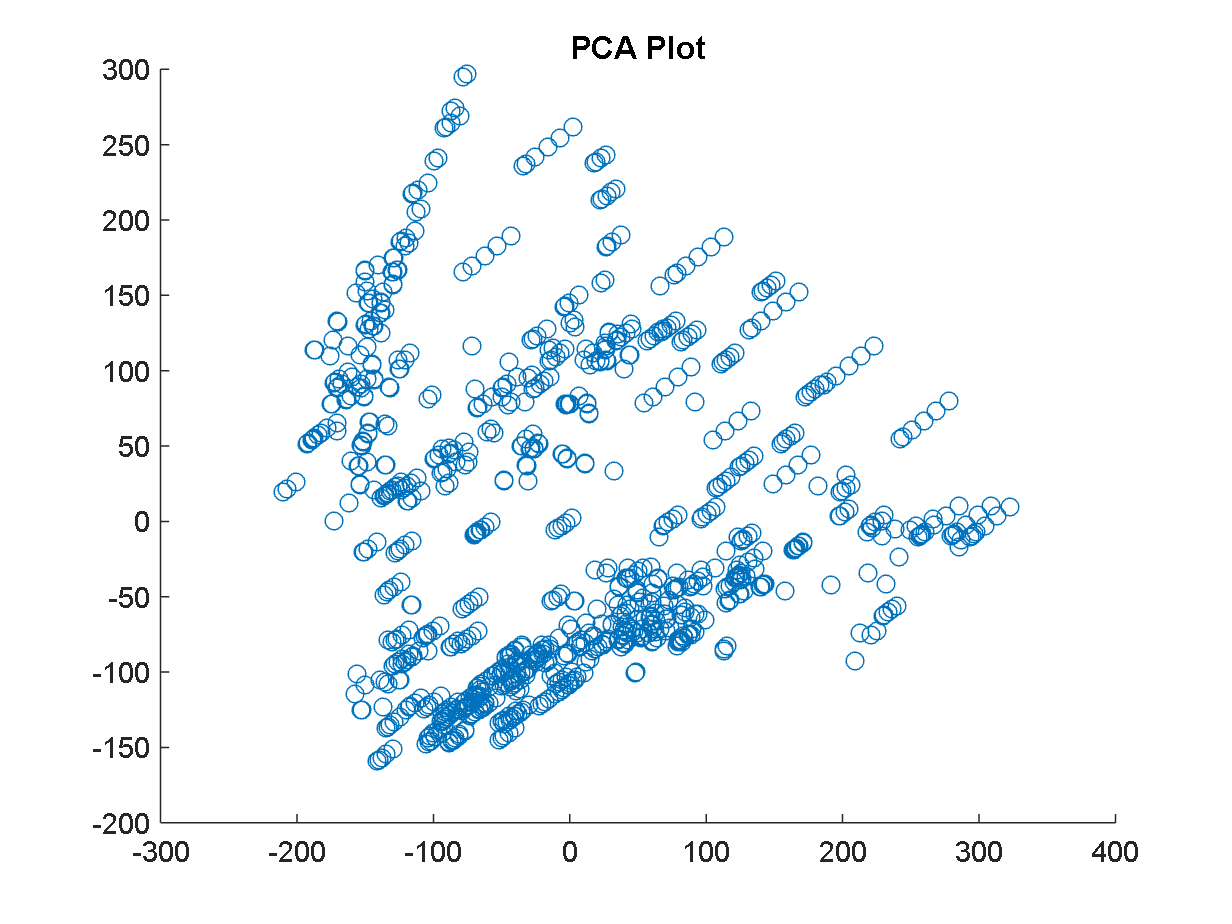

z = df.csMPa;
s = df.cement; % 4th dimension shown by size
c = df.slag; % 5th dimension shown by color

graph = scatter3(x,y,z,s,c);
xlabel('Coarseaggregate (kg/m3)');
ylabel('Water (kg/m3)');
zlabel('Compressive Strength (MPa)');

title('5D')
color = colorbar;
color.Label.String = 'Kg/m3';

**Bonus Activity:** Perform a PCA using only 2 features. Plot the results of the PCA, and a scatterplot of the raw data. Are they different? If so, how and why?

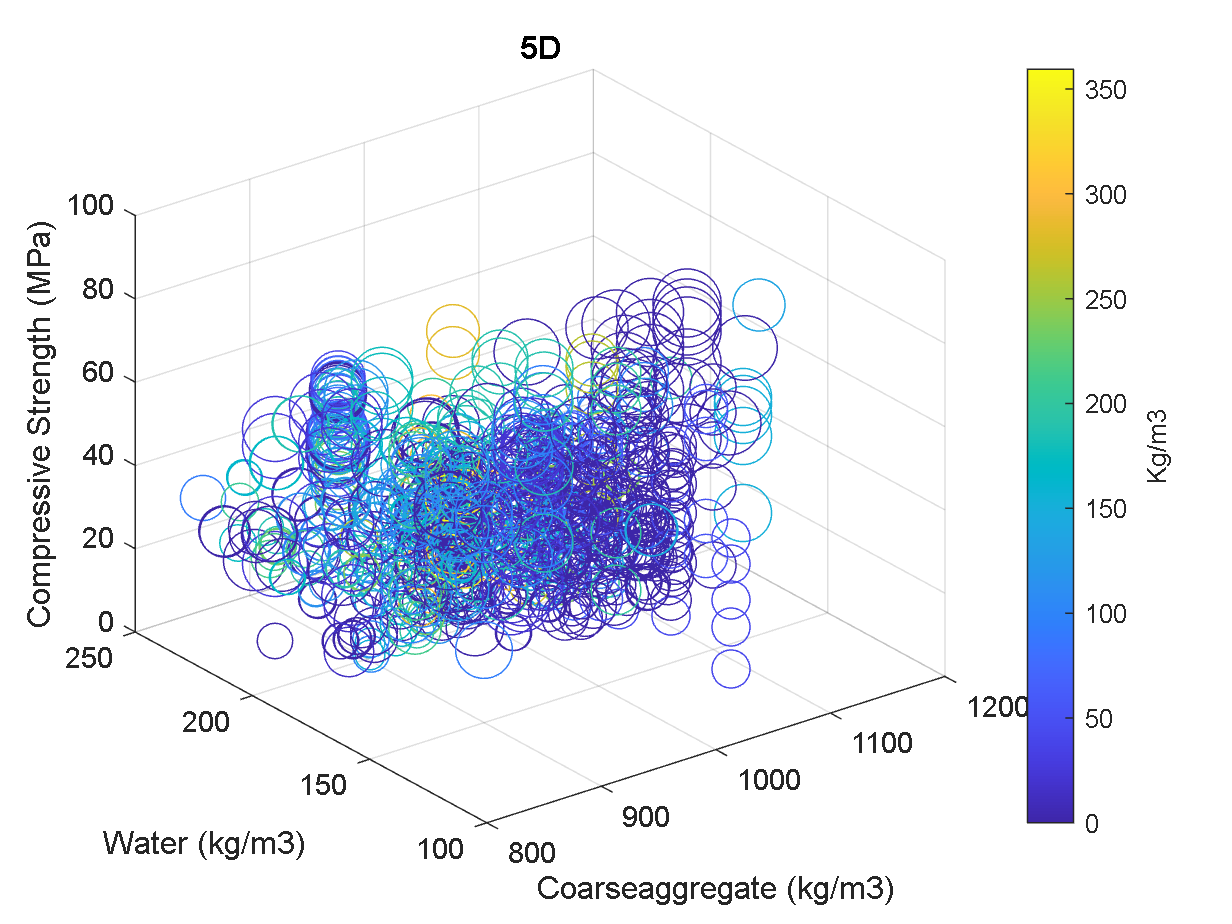

% PCA
clf % Clears former plot parameters
df_matrix_flyash_water = table2array(df(:,[3,4]));
[coeff, score] = pca(df_matrix_flyash_water);


% Create scatter plot of principal component scores
hold on
scatter(score(:,1), score(:,2), 'filled');
scatter(df, 'flyash', 'water', 'filled');
legend("PCA", "Original")
xlabel('');
ylabel('');
hold off

#### Plotting Tip

Matlabs creates interactive plots for exploring data results. You can rotate plots, zoom in and zoom out, and double click to openen up a host of other options It is particularly useful for exploring 3-D scatter plots